
% Define input and output data
X = [ -0.5 -0.5 +0.3 -0.1; -0.5 +0.5 -0.5 +1.0] % Input Vector

X =    -0.5000   -0.5000    0.3000   -0.1000
   -0.5000    0.5000   -0.5000    1.0000


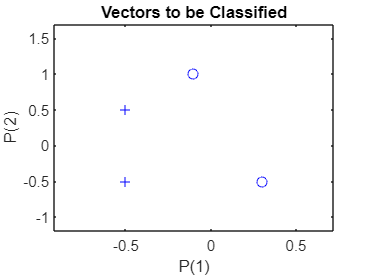

T = [1 1 0 0]; % Target Vector
plotpv(X,T);

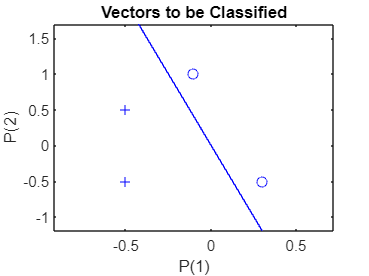

% Create perceptron
net = perceptron;
net = configure(net,X,T);
% Replot with the neuron s initial attempt at classification.
plotpv(X,T);
plotpc(net.IW{1},net.b{1});

% convert the input and target data intonsequential data
XX = repmat(con2seq(X),1,3);
TT = repmat(con2seq(T),1,3);
net = adapt(net,XX,TT);
plotpc(net.IW{1},net.b{1});

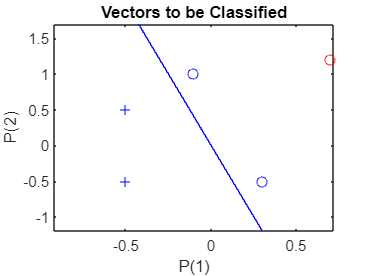

% classify new input vector, for example [0.7; 1.2].
x = [0.7; 1.2];
y = net(x);
plotpv(x,y);
point = findobj(gca,'type','line');
point.Color = 'red';
hold on;
plotpv(X,T);
plotpc(net.IW{1},net.b{1});
hold off;